# Estructuras de datos: Matrices

## Crear vectores con el operador dos puntos y la función `linspace`

### Ejercicio 1

Explique cómo es obtenido el valor del paso, o espaciamiento, de la función `linspace`. Primero cree un par de ejemplos como referencia.

*Ejercicio tomado de Attaway, 2022.*

### Solución

Con el método linspace lo que no sabemos es el espaciamineto que habrá entre cada termino de nuestro arreglo, pero si sabemos o podemos 

definir cuantos numero queremos que haya, esto sucede ya que linspace divide el numero datos que nosotros queremos en partes iguales.

### Ejercicio 2

Si se requiere graficar la función $f\left(x\right)=\sqrt{x}$, con $x\in \left\lbrack 0,5\right\rbrack$. ¿Cuál sería la mejor forma de crear un vector que contenga los valores de $x$? ¿Por qué?

### Solución

La mejor opción sería usar linspace, ya que por defecto si no indicamos cuantos valores queremos nos dara 100 valores, estos 100 valores serán los puntos que vamos a graficar y por lo tanto se verá de forma más explicita nuestra gráfica. 

## Concatenar matrices

### Ejercicio 1

Realizar las siguientes actividades:

- Crear un escalar y nombrarlo $a$.

- Crear un vector $1\times 3$ y nombrarlo $b$.

- Crear una matriz $2\times 2$ y nombrarla $C$.

- Crear una matriz de la siguiente forma:


$$\left\lbrack \begin{array}{cccc}
b_1  & b_2  & b_3  & a\\
a & a & C_{11}  & C_{12} \\
C_{11}  & C_{12}  & C_{21}  & C_{22} \\
C_{21}  & C_{22}  & a & a
\end{array}\right\rbrack$$


### Solución

a=1;
b=[2 3 4];
C=[5 6  ; 7 8];
M1=[b a];
M2=[a a ; C];
M3=[C ; a a ];
M=[M1 ; M2 M3]

M =      2     3     4     1
     1     1     5     6
     5     6     7     8
     7     8     1     1


### Ejercicio 2

Cree una matriz como la que se muestra más abajo utilizando la notación de vectores para crear vectores con distanciado constante, y/o la función `linspace` para crear las filas.


$$B=\left\lbrack \begin{array}{ccccccccc}
1 & 4 & 7 & 10 & 13 & 16 & 19 & 22 & 25\\
72 & 66 & 60 & 54 & 48 & 42 & 36 & 30 & 24\\
0 & 0\ldotp 125 & 0\ldotp 250 & 0\ldotp 375 & 0\ldotp 500 & 0\ldotp 625 & 0\ldotp 750 & 0\ldotp 875 & 1\ldotp 000
\end{array}\right\rbrack$$


*Ejercicio tomado de Gilat, 2006.*

### Solución

clear
B=[1:3:25 ; 72:-6:24 ; linspace(0,1,9)]

B =     1.0000    4.0000    7.0000   10.0000   13.0000   16.0000   19.0000   22.0000   25.0000
   72.0000   66.0000   60.0000   54.0000   48.0000   42.0000   36.0000   30.0000   24.0000
         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000


## Redimensionar matrices

### Ejercicio 1

Tomando como base la matriz final del anterior ejercicio, realizar las siguientes actividades:

- Redimensionar a una matriz $8\times 2$, ¿es posible?

- Resimensionar a una matriz $5\times 3$, ¿es posible?

- ¿La matriz es mágica? Verificar todas las condiciones.

Ahora bien, para los literales 1 y 2, ¿cómo se podría averiguar si el redimensionamiento es posible antes de intentarlo?

**Nota:** Utilizar la función `rem` o `mod` para responder la última pregunta.

### Solución

mod(27,8)

ans = 3

**Para la primer pregunta no es posible ya que sobrarían 3 datos **

rem(27,5)

ans = 2

**Para el segundo caso tampoco en posible ya que sobrarían 2 elementos** 

sum(B)

ans =    73.0000   70.1250   67.2500   64.3750   61.5000   58.6250   55.7500   52.8750   50.0000


sum(B,2)

ans =   117.0000
  432.0000
    4.5000


sum(diag(B))

ans = 67.2500

**Como podemos observar ni el columnas, ni el filas da el mismo valor, por lo tanto no es una matriz mágica. **

### Ejercicio 2

Cree una matriz mágica de $5\times 5$ llamada `a`.

- `a` por una constante, como 2, ¿también es una matriz mágica?

- Si eleva al cuadrado cada elemento de `a`, ¿la nueva matriz es una matriz mágica?

- Si suma una constante a cada elemento, ¿la nueva matriz es una matriz mágica?

-  Cree una matriz $2\times 2$ a partir de los siguientes componentes:

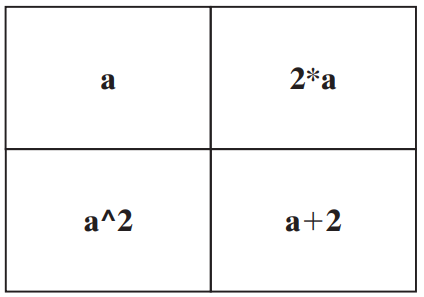

¿Su resultado es una matriz mágica? ¿La forma en la que ordena los componentes afecta su respuesta?

*Ejercicio tomado de Moore, 2007.*

### Solución

clear
a=magic(5);
%pregunta 1
b=2.*a;
sum(b)

ans =    130   130   130   130   130


sum(b,2)

ans =    130
   130
   130
   130
   130


sum(diag(b))

ans = 130

sum(diag(fliplr(b)))

ans = 130

**podemos concluir que la pregunta uno si es mágica **

%pregunta 2
c=a.^2;
sum(c)

ans =         1055        1105        1205        1105        1055


sum(c,2)

ans =         1155
        1055
        1105
        1055
        1155


sum(diag(c))

ans = 1005

sum(diag(fliplr(c)))

ans = 855

**Si elevamos al cuadrado la nueva matriz no es mágica **

%pregunta 3 
d=a+2;
sum(d)

ans =     75    75    75    75    75


sum(d,2)

ans =     75
    75
    75
    75
    75


sum(diag(d))

ans = 75

sum(diag(fliplr(d)))

ans = 75

**La nueva matriz si es una matriz mágica **

%pregunta 4 
a=3;
M=[a 2.*a ; a.^2 a+2]

M =      3     6
     9     5


**No es una matriz mágica ya que posee la operación de elevar al cuadrado por lo cual afectara a los resultados**

## Ordenar matrices

### Ejercicio

Cargar el archivo "`patients.mat`". ¿Qué variables tiene?

Una vez cargado el archivo, concatenar tres vectores columna numéricos para formar una matriz y ordenarla en función de alguna de las columnas. ¿Cómo se interpretaría el resultado en función de la columna escogida?

### Solución

clear 
load patients.mat
whos

  Name                            Size            Bytes  Class      Attributes

  Age                           100x1               800  double               
  Diastolic                     100x1               800  double               
  Gender                        100x1             13012  cell                 
  Height                        100x1               800  double               
  LastName                      100x1             13216  cell                 
  Location                      100x1             15808  cell                 
  SelfAssessedHealthStatus      100x1             13140  cell                 
  Smoker                        100x1               100  logical              
  Systolic                      100x1               800  double               
  Weight                        100x1               800  double               



M=[Age Height Smoker];
edad=sortrows(M,1,"descend")

edad =     50    68     0
    50    72     1
    49    64     0
    49    68     1
    49    63     1
    49    70     0
    48    71     1
    48    65     0
    48    66     0
    48    64     1


**En esté caso se ordeno mediante la columna edad de manera descendente, es decir, de mayor a menor, también se incluyyen columnas como el peso**

**y si fuman**

## Indexación de matrices

### Ejercicio

El archivo "`Tema03_Auxiliar_TemperaturaMediaMensual.mat`" contiene información acerca de la temperatura media mensual (ºC) desde el 2003 hasta el 2006 (columnas) para cada mes del año (filas), de una estación meteorológica.

Extraer los registros de 2003 y 2004 de marzo, y luego extraer los registros de 2005 y 2006 también de marzo. ¿En cuál de los periodos hay una mayor temperatura?

Después, realizar lo siguiente:

- Obtener el promedio de temperatura de cada mes a lo largo de todos los años.

- Extraer todos los registros (meses) del último año.

- Obtener los números de fila de los registros (meses) que son mayores al promedio a lo largo de todos los años.

- Extraer todos los registros (meses) que son mayores o iguales que el promedio a lo largo de todos los años.

¿Lo meses de 2006 que superan al promedio son los mismos para el resto de años?

**Nota 1:** Para la condición utilizar la operación relacional "mayor o igual que" $\ge$.

**Nota 2:** Para obtener el promedio se utiliza la función `mean`. 

### Solución

clear 
load Tema03_Auxiliar_TemperaturaMediaMensual.mat
whos

  Name                          Size            Bytes  Class     Attributes

  TemperaturaMediaMensual      12x4               384  double              



A=TemperaturaMediaMensual(: , 1:2)

A =    15.4000   14.9000
   15.8000   15.8000
   15.6000   16.1000
   15.8000   15.8000
   15.3000   15.7000
   15.1000   14.3000
       NaN   14.7000
   14.5000   14.1000
   14.9000   14.5000
   15.8000   15.1000


B=TemperaturaMediaMensual(: , end-1:end)

B =    15.3000       NaN
   15.7000   15.7000
   15.6000   15.5000
   15.9000   15.2000
   15.2000   14.8000
   15.2000   14.5000
   14.2000   14.4000
   14.5000   14.8000
   15.0000   15.1000
   15.2000   15.2000


sum(A>=B)

ans =      8     6


**Por lo tanto podemos decir que en el periodo de 2003 a 2004 hubo más temperatura**

prom=mean(TemperaturaMediaMensual,2)

prom =        NaN
   15.7500
   15.7000
   15.6750
   15.2500
   14.7750
       NaN
   14.4750
   14.8750
   15.3250


c=TemperaturaMediaMensual(: ,end)

c =        NaN
   15.7000
   15.5000
   15.2000
   14.8000
   14.5000
   14.4000
   14.8000
   15.1000
   15.2000


d=c>=prom

d = 12×1 logical array
   0
   0
   0
   0
   0
   0
   0
   1
   1
   0


f=TemperaturaMediaMensual>=prom

f = 12×4 logical array
   0   0   0   0
   1   1   0   0
   0   1   0   0
   1   1   1   0
   1   1   0   0
   1   0   1   0
   0   0   0   0
   1   0   1   1
   1   0   1   1
   1   0   0   0
